## Parte 4

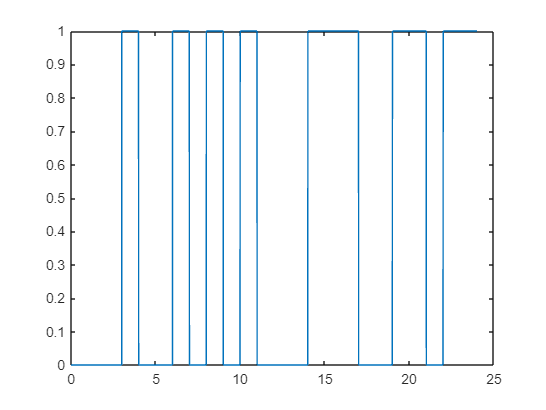

T = 24;              %segundos
Ts = (0.001)/2;     %segundos/muestra
t = 0:Ts:T;          %vector tiempo de muestreo

f((t>0)&t<=3)=0;
f((t>3)&(t<=4))=1;
f((t>4)&(t<=6))=0;
f((t>6)&(t<=7))=1;
f((t>7)&(t<=8))=0;
f((t>8)&(t<=9))=1;
f((t>9)&(t<=10))=0;
f((t>10)&(t<=11))=1;
f((t>11)&(t<=14))=0;
f((t>14)&(t<=17))=1;
f((t>17)&(t<=19))=0;
f((t>19)&(t<=21))=1;
f((t>21)&(t<=22))=0;
f((t>22)&(t<=24))=1;
plot(t,f)

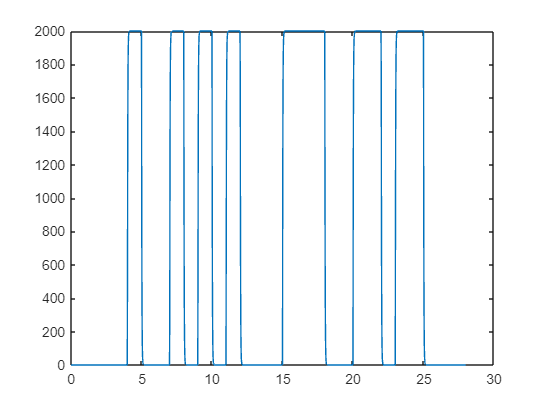


%Convolucion con la funcion de simulink
ht = out.hout.data;
t1 = out.hout.time;
y2 = conv(f,ht,'full'); 
time2 = t1(1)+t(1):0.001/2:t1(end)+t(end);
plot(time2,y2)

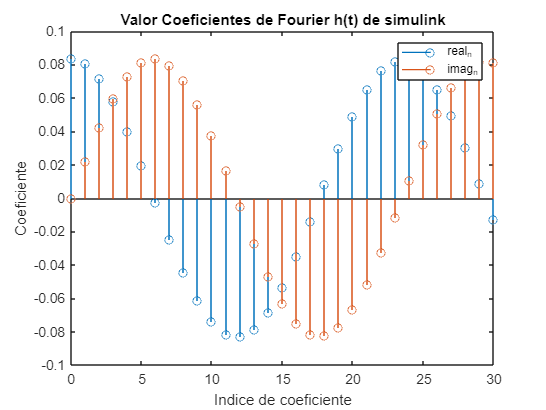


%h(t) desde simulink
%Calculo de coeficientes de Fourier
N = 30; 
realc = zeros(1,N+1);
imagc = zeros(1,N+1);

for n=0:N
    cosTerm = cos(2*pi*transpose(t1)*n/T);
    sinTerm = sin(2*pi*transpose(t1)*n/T);
    
    realc(n+1) = (2*Ts/T)*sum(transpose(ht).*cosTerm);
    imagc(n+1) = (2*Ts/T)*sum(transpose(ht).*sinTerm);
end

complex_coeffs = realc+1i.*imagc;
modulos = abs(complex_coeffs);
angulos = angle(complex_coeffs);

%Visualizar coeficientes 

stem(0:N, realc)
hold on
stem(0:N, imagc)
hold off
xlabel('Indice de coeficiente')
ylabel('Coeficiente')
legend('real_n','imag_n')
title('Valor Coeficientes de Fourier h(t) de simulink')

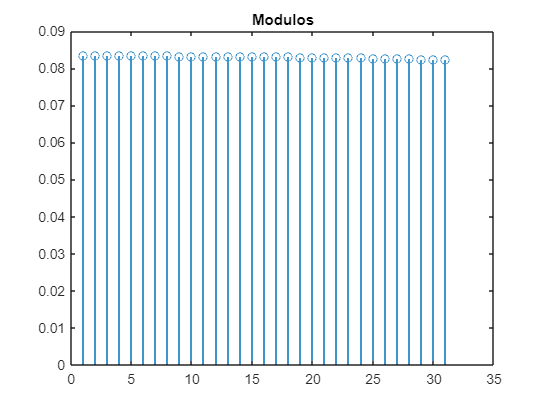


stem(modulos),title('Modulos')

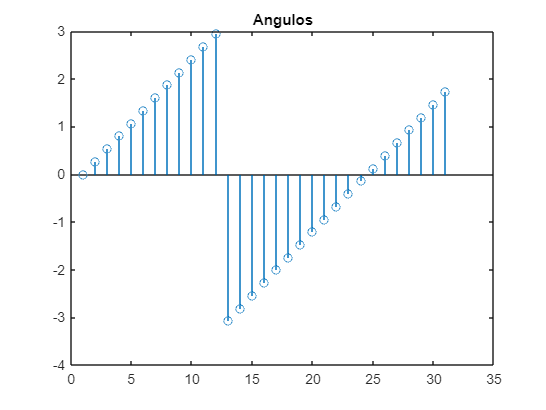

stem(angulos),title('Angulos')

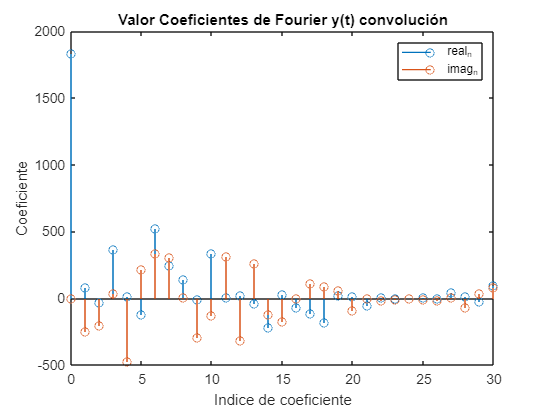

%Coeficientes de Fourier convolución
%Borrar despues

%Calculo de coeficientes de Fourier
N = 30; 
realc = zeros(1,N+1);
imagc = zeros(1,N+1);

for n=0:N
    cosTerm = cos(2*pi*time2*n/T);
    sinTerm = sin(2*pi*time2*n/T);
    
    realc(n+1) = (2*Ts/T)*sum(y2.*cosTerm);
    imagc(n+1) = (2*Ts/T)*sum(y2.*sinTerm);
end

complex_coeffs = realc+1i.*imagc;
modulos = abs(complex_coeffs);
angulos = angle(complex_coeffs);

%Visualizar coeficientes 

stem(0:N, realc)
hold on
stem(0:N, imagc)
hold off
xlabel('Indice de coeficiente')
ylabel('Coeficiente')
legend('real_n','imag_n')
title('Valor Coeficientes de Fourier y(t) convolución')

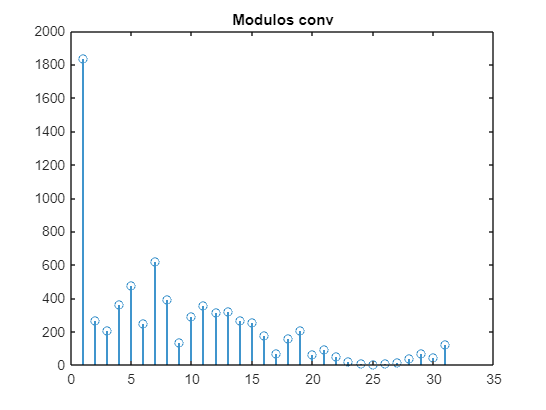


stem(modulos),title('Modulos conv')

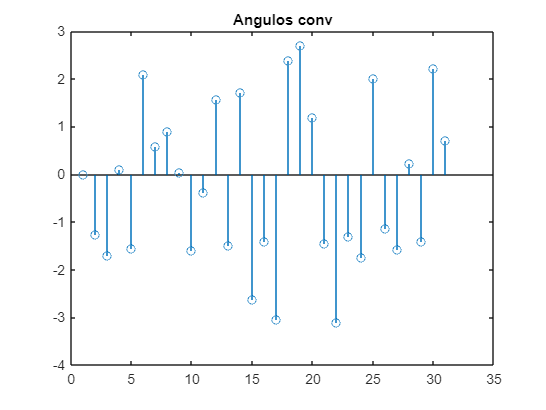

stem(angulos),title('Angulos conv')

**b) Determine los coeficientes de la Serie de Fourier de la Señal x(t) (estos coeficientes fueron obtenidos en la Tarea 2) y de la señal resultado de la convolución y(t). ¿Existen diferencias en magnitud? ¿Existen diferencias en ángulo? **

Al observar los resultados de las gráficas de magnitud 

**d) Tome ahora los coeficientes de la Serie de Fourier de x(t) y los de la señal h(t), multiplique las magnitudes y sume algebraicamente los ángulos. ¿El resultado tiene alguna relación con los coeficientes de la señal y(t) en el ítem b)? Compare magnitud y ángulo.**